### Project 2 OFDM

a. generate pilot signal

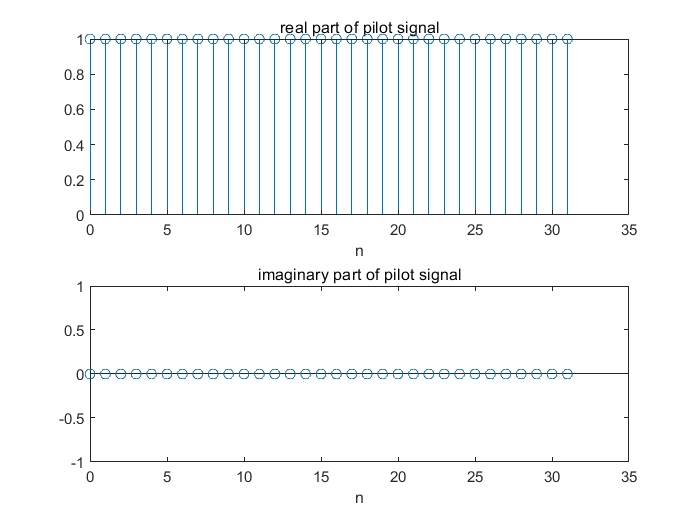

clc, clear;

%a = randn(1, 32) + 1j*randn(1,32);
a = ones(1,32);
n = 0 : length(a)-1;

%initialize
cp = length(a);
Hn = ones(1,length(a));

figure;
subplot(211);
stem(n, real(a)), xlabel('n');
title("real part of pilot signal");
subplot(212);
stem(n, imag(a)), xlabel('n');
title("imaginary part of pilot signal");

b. preprocess the signal and transmit to equivalent DT wireless channel

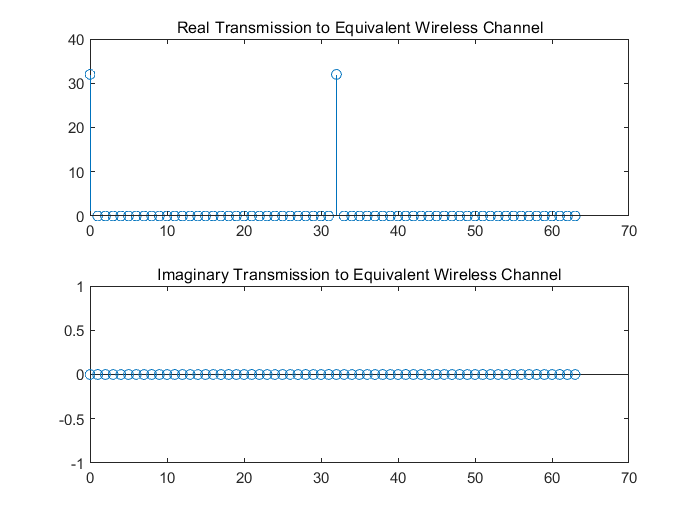

x_in = block1(a,cp);

c. DT signal converts to CT signal

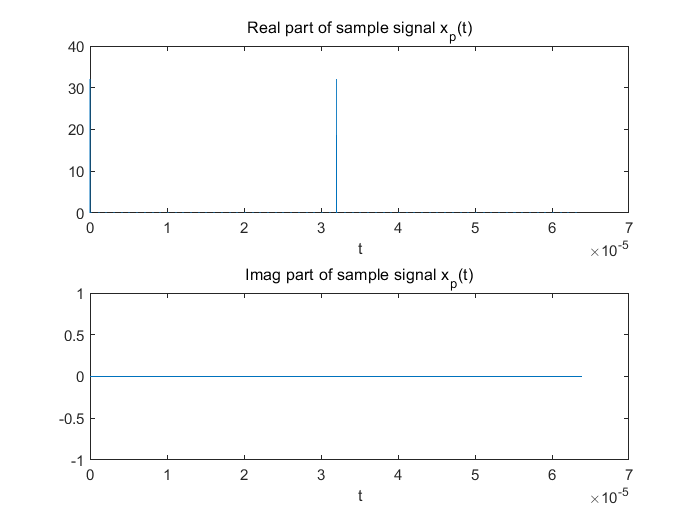

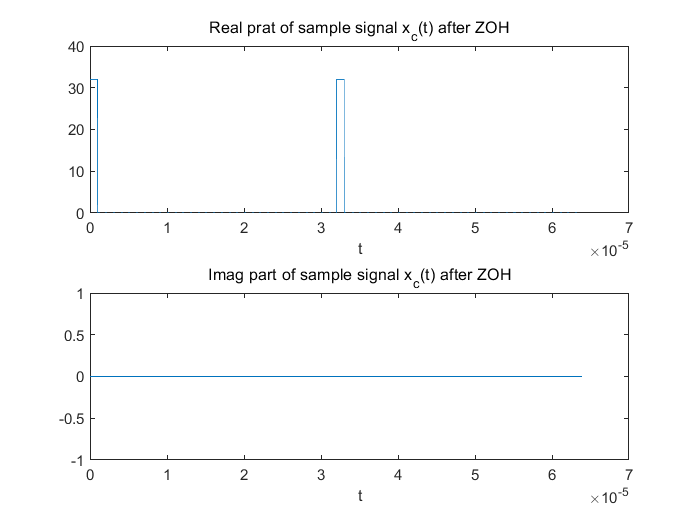

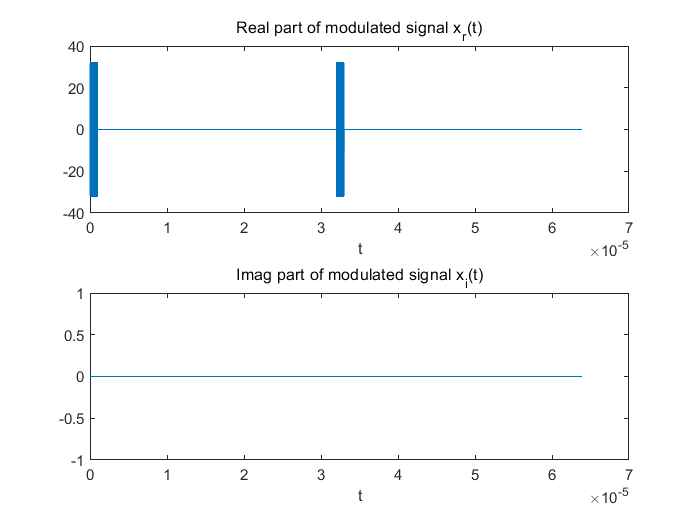

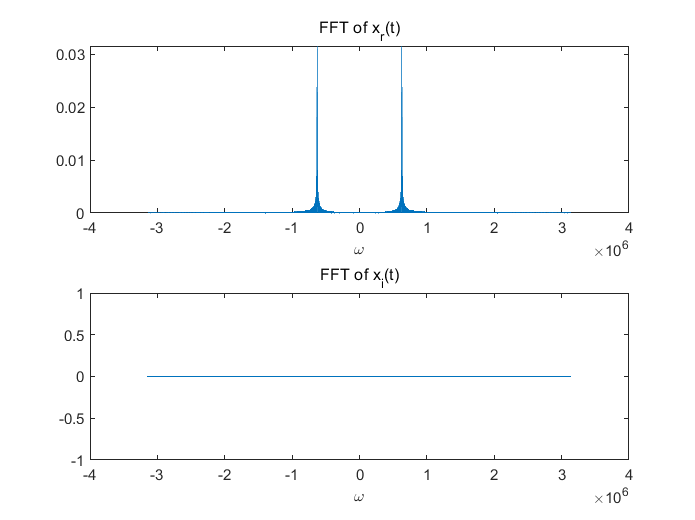

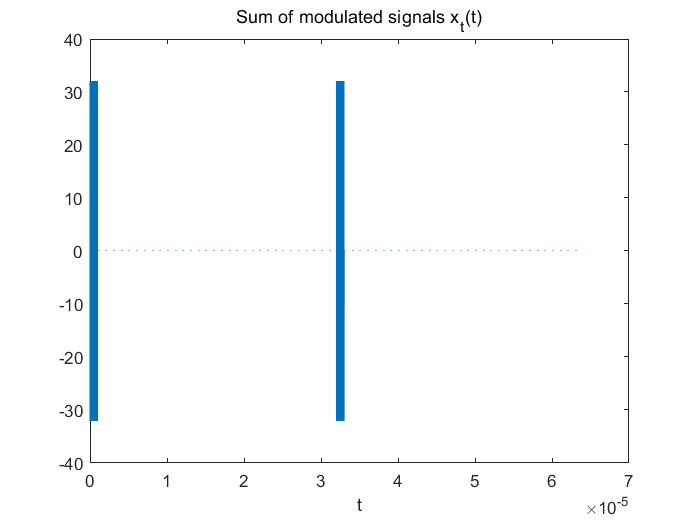

y_ct = block3(x_in);

d. CT signal converts to DT signal

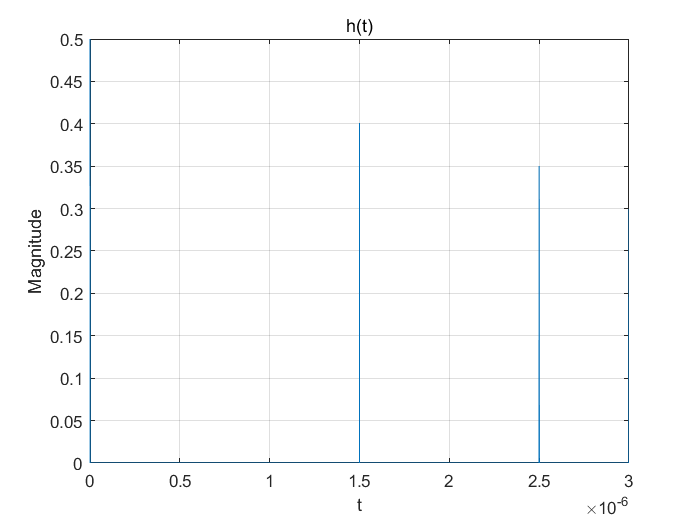

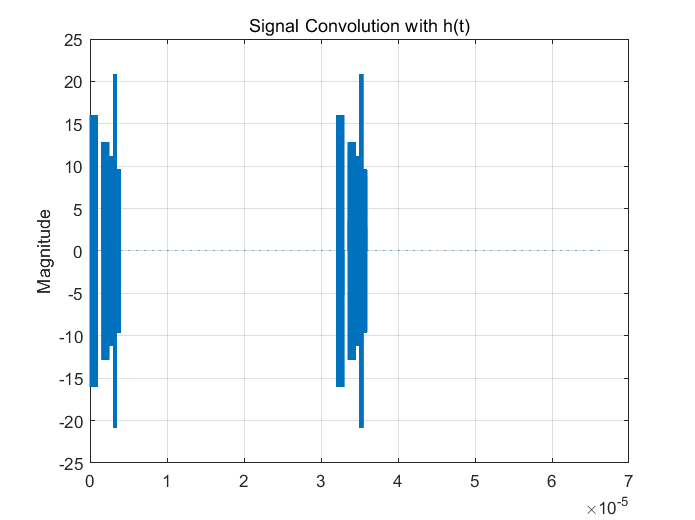

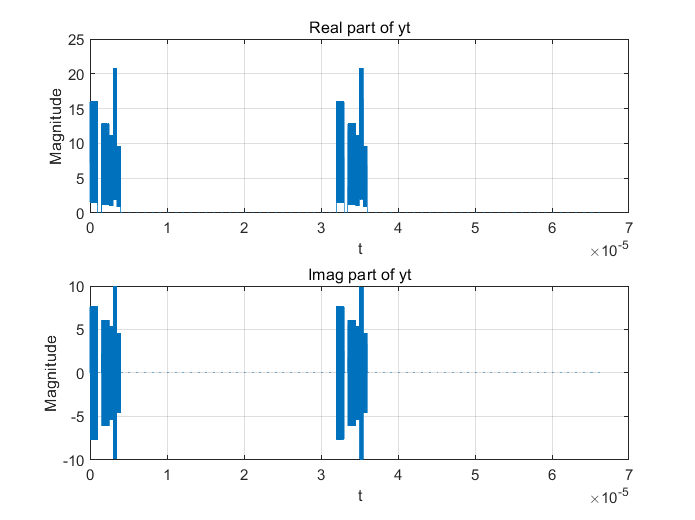

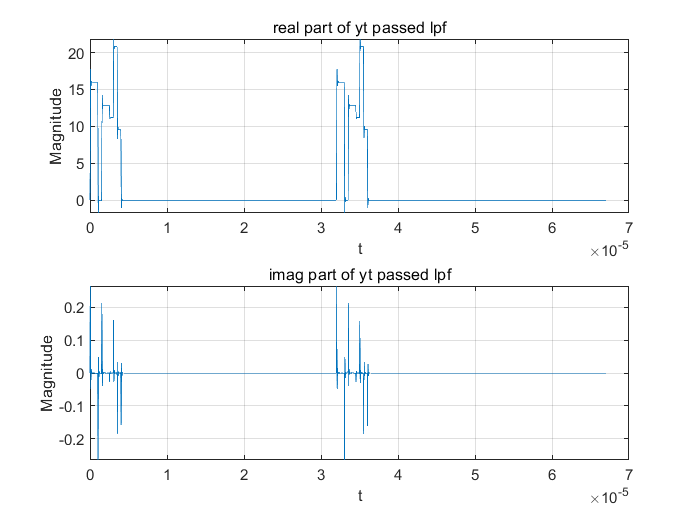

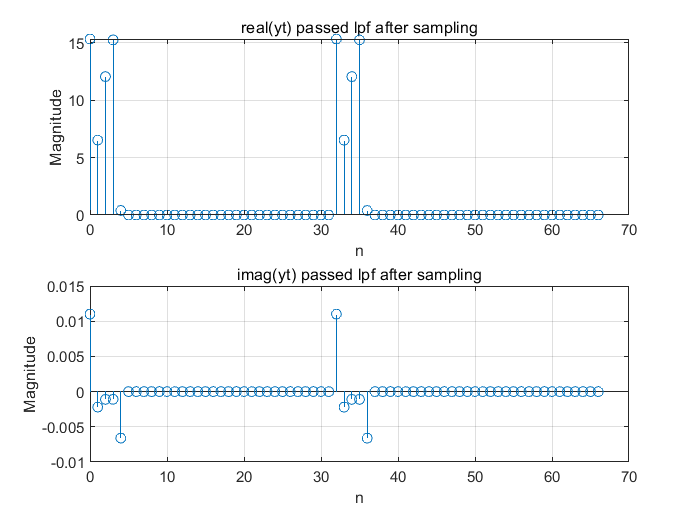

y_dt = block4(y_ct);

f. receive pilot signal

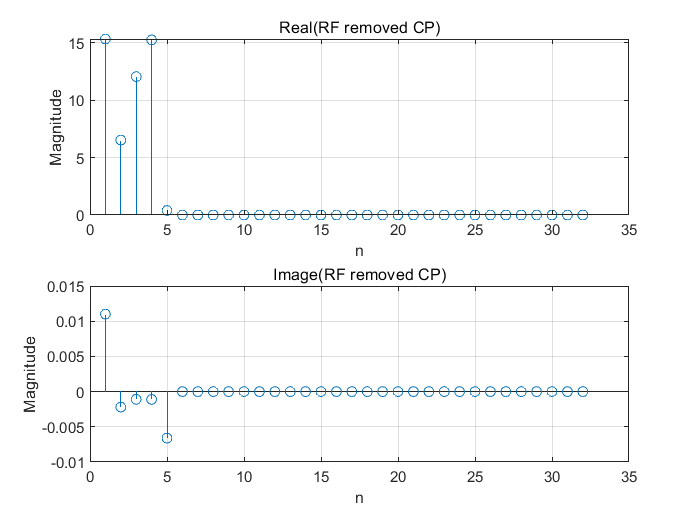

x_out = block2(y_dt, Hn, length(a), cp);

g. channel estimation and find the length of CP

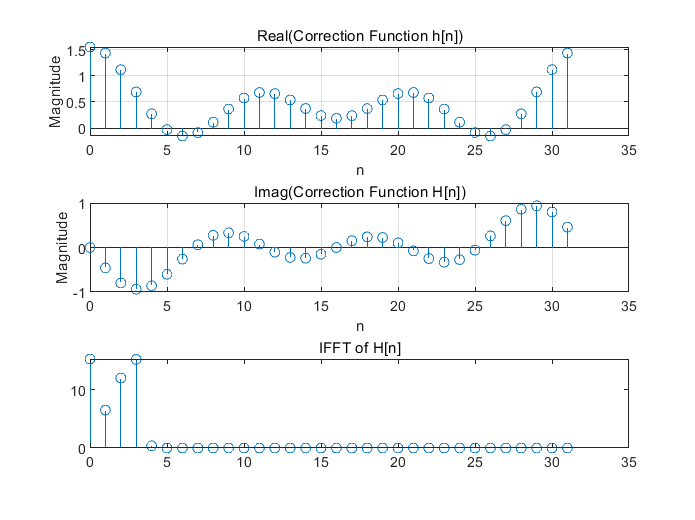

Hn = x_out ./ a;
hn = length(Hn) * ifft(Hn);
cp = 4; %according to the figure of IFFT of H[n]

figure
subplot(3,1,1), stem(0:length(Hn)-1, real(Hn));
grid on;xlabel('n');ylabel('Magnitude');
title('Real(Correction Function h[n])');

subplot(3,1,2), stem(0:length(Hn)-1, imag(Hn));
grid on;xlabel('n');ylabel('Magnitude');
title('Imag(Correction Function H[n])');

subplot(3,1,3), stem(0:length(Hn)-1, abs(hn));
title('IFFT of H[n]');

h. transmit random signal

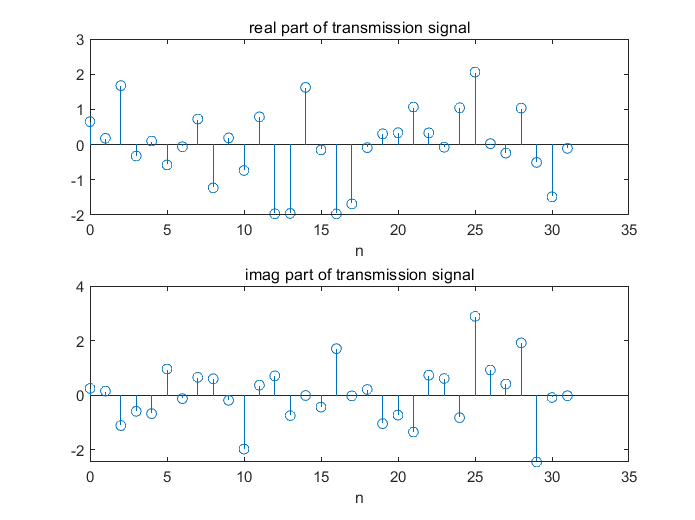

b = randn(1,32)+1j*randn(1,32);
n = 0:length(b)-1;

figure
subplot(211),stem(n, real(b)), xlabel('n');
title("real part of transmission signal");
subplot(212),stem(n, imag(b)), xlabel('n');
title("imag part of transmission signal");

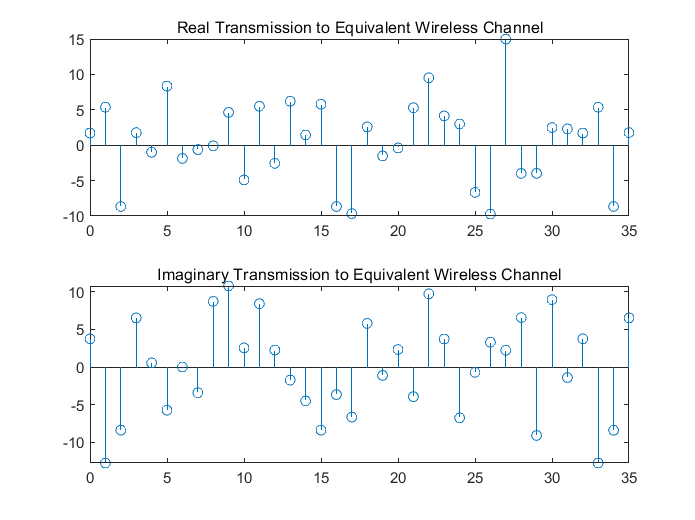


x_in = block1(b,cp);

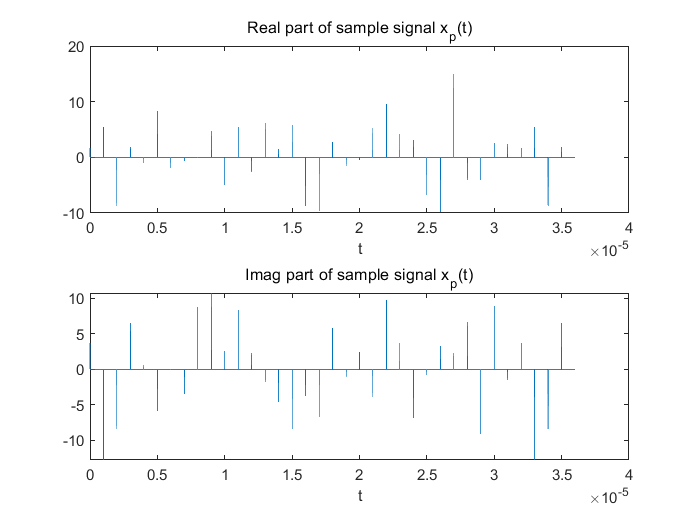

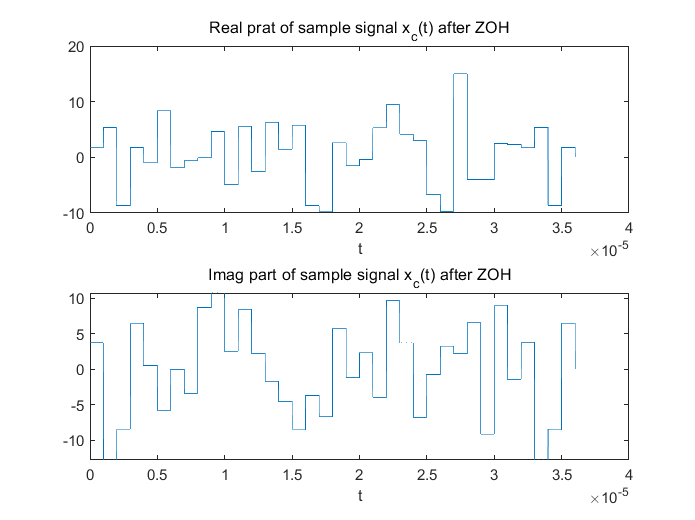

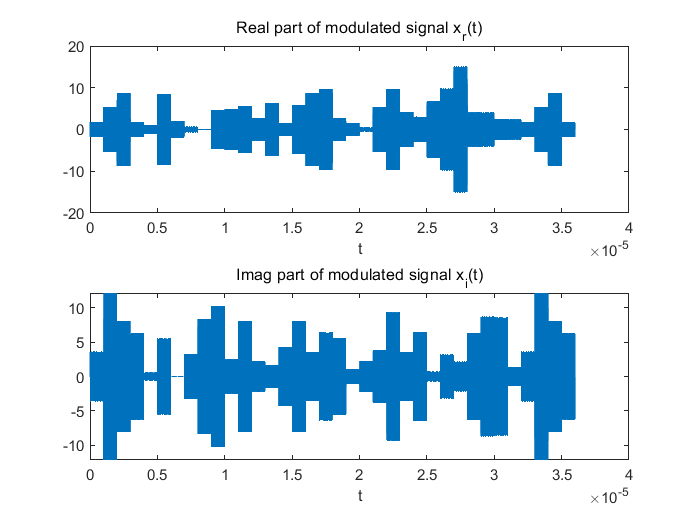

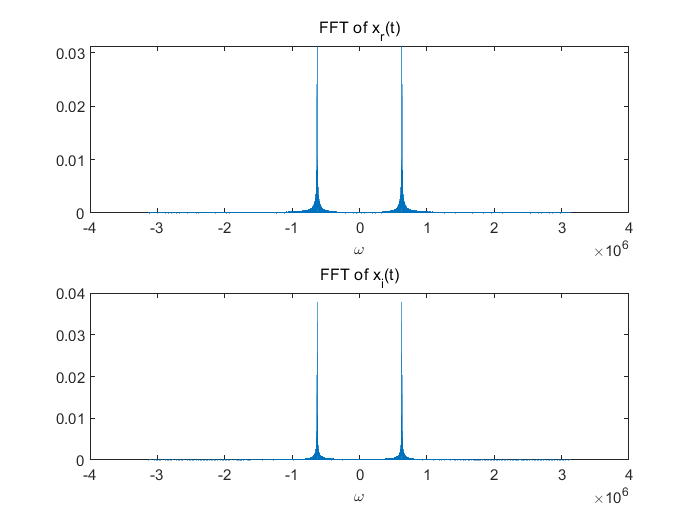

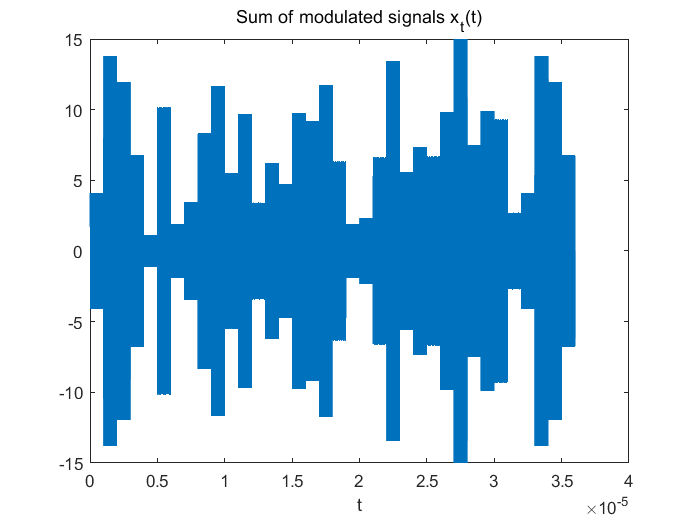

x_ct = block3(x_in);

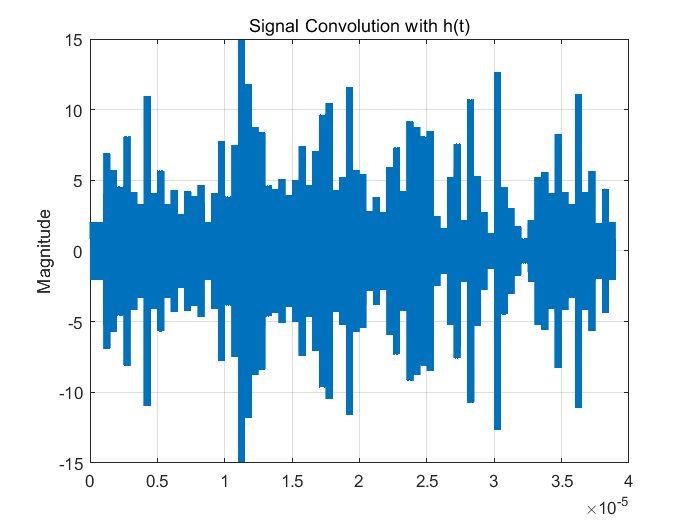

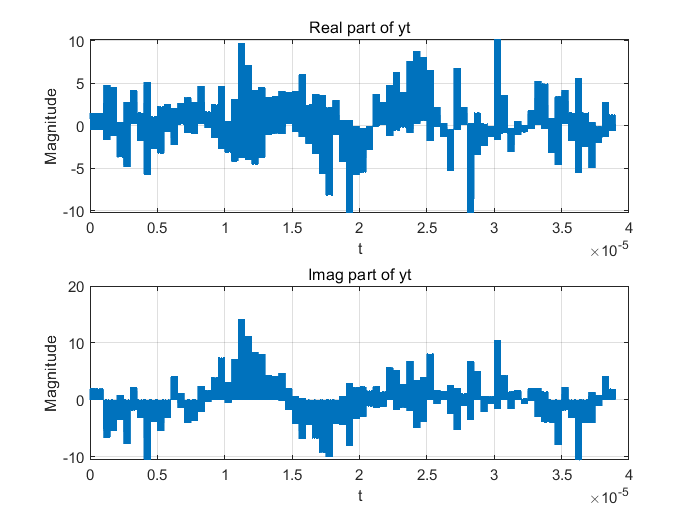

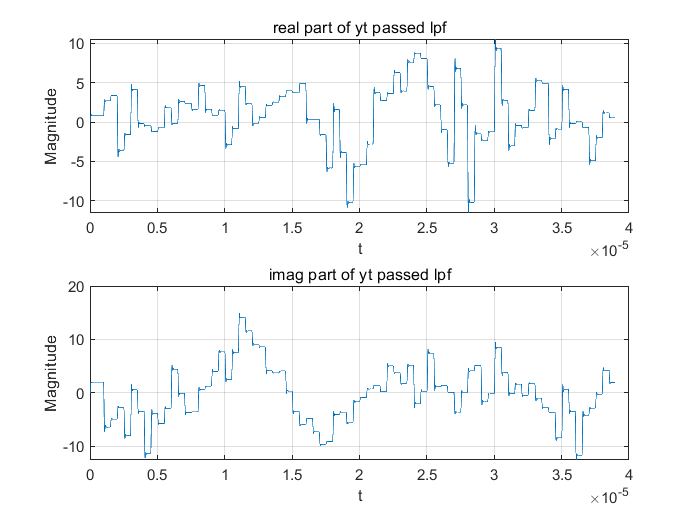

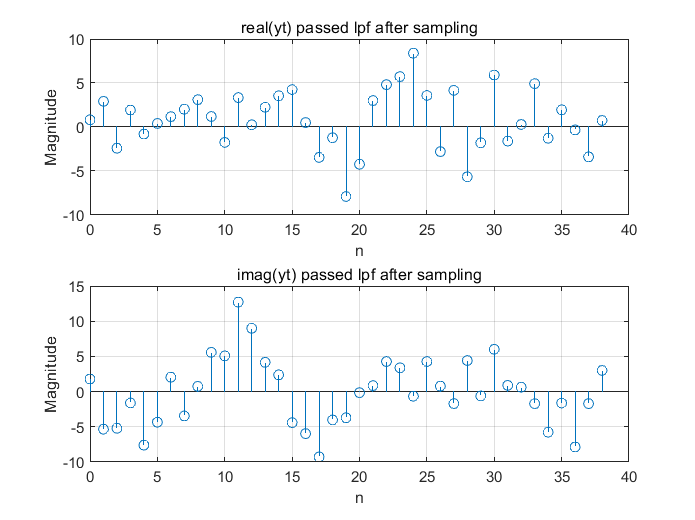

x_dt = block4(x_ct);

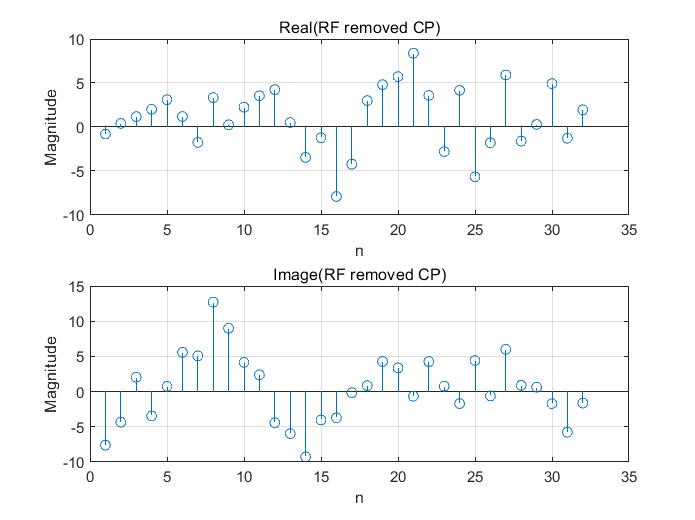

x_out = block2(x_dt, Hn, length(b),cp);

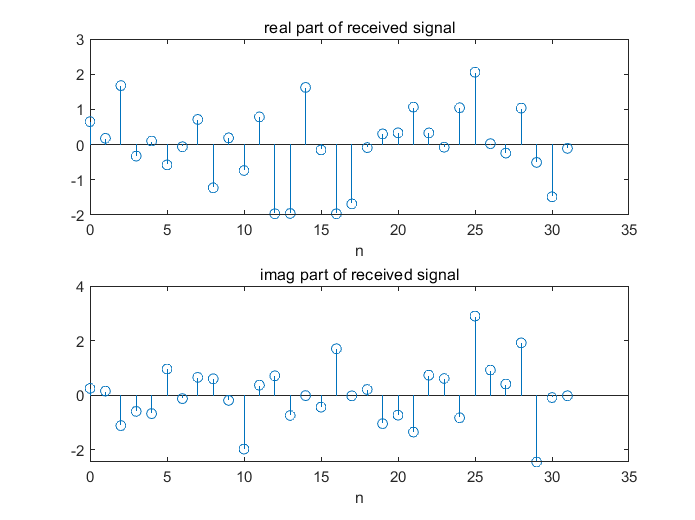


figure
subplot(211),stem(n, real(x_out)), xlabel('n');
title("real part of received signal");
subplot(212),stem(n, imag(x_out)), xlabel('n');
title("imag part of received signal");

i. compare with origin signal and received signal

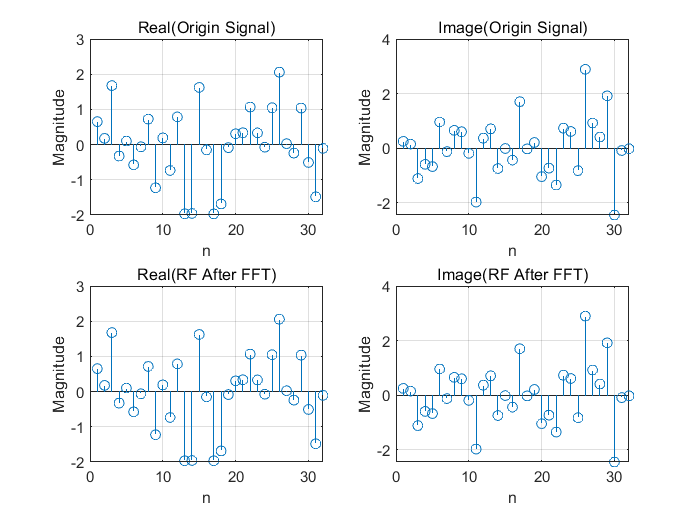

figure
subplot(2,2,1);
stem(real(b));
grid on;title('Real(Origin Signal)');
xlabel('n');ylabel('Magnitude');

subplot(2,2,2);
stem(imag(b));
grid on;title('Image(Origin Signal)');
xlabel('n');ylabel('Magnitude');

subplot(2,2,3);
stem(real(x_out));
grid on;title('Real(RF After FFT)');
xlabel('n');ylabel('Magnitude');

subplot(2,2,4);
stem(imag(x_out));
grid on;title('Image(RF After FFT)');
xlabel('n');ylabel('Magnitude');

j. error analysis

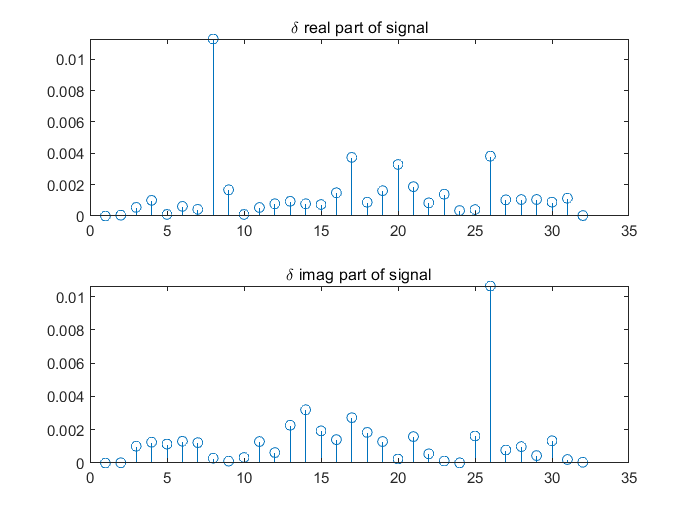

delta_real = abs(real(x_out)-real(b));
dleta_imag = abs(imag(x_out)-imag(b));

figure
subplot(2,1,1), stem(delta_real), 
title('\delta real part of signal');
subplot(2,1,2), stem(dleta_imag), 
title('\delta imag part of signal');

Block1:

function x1=block1(a,cp)
%数据长度---傅里叶反变换后的x长度为N
N=length(a);
%将a当做频率上的数据，进行傅里叶反变换得到时域上的信号
x=N*ifft(a);
%添加cp,获得x1
x1=[x(N-cp+1:N),x]; %cp = 4 > channel delay
%取得添加cp后信号的长度
N0=length(x1);

figure
subplot(2,1,1),stem(0:N0-1,real(x1));
title("Real Transmission to Equivalent Wireless Channel");
subplot(2,1,2),stem(0:N0-1,imag(x1));
title("Imaginary Transmission to Equivalent Wireless Channel");
end

Block 2:

function get_block2 = block2(y_dt_cp,Hn,N,L_cp)
% remove CP
%L_cp = 4;%length of cp
y_dt =  y_dt_cp((L_cp+1):(N+L_cp));

figure
subplot(2,1,1);
stem(real(y_dt));
grid on;title('Real(RF removed CP)');xlabel('n');ylabel('Magnitude');

subplot(2,1,2);
stem(imag(y_dt));
grid on;title('Image(RF removed CP)');xlabel('n');ylabel('Magnitude');

% fft
ss = fft(y_dt);
get_block2 = ss / N ./ Hn; 

end

Block 3:

function signal_t = block3(signal_in)
    Ts = 1e-6; %sample period
    fc = 1e8; %carrier frequency
    
    t = 0:Ts*1e-3:length(signal_in)*Ts;

    %CT signal from DAC transmitter
    x_p = [upsample(signal_in, 1e3), 0];
    
    figure
    subplot(2,1,1), plot(t, real(x_p)), xlabel('t');
    title('Real part of sample signal x_p(t)');
   
    subplot(2,1,2), plot(t, imag(x_p)), xlabel('t');
    title('Imag part of sample signal x_p(t)');
    
    %CT signal through Zero-Order Hold
    x_o = repmat(x_p(1:1e3:(length(x_p)-1e3)), 1e3, 1);
    x_c = [reshape(x_o, 1, []), x_p(end)];
    
    figure
    subplot(2,1,1), plot(t, real(x_c)), xlabel('t');
    title('Real prat of sample signal x_c(t) after ZOH');
    
    subplot(2,1,2), plot(t, imag(x_c)), xlabel('t');
    title('Imag part of sample signal x_c(t) after ZOH');
    
    %modulation of CT signal
    x_r = real(x_c) .* cos(2*pi*fc*t);
    x_i = imag(x_c) .* sin(2*pi*fc*t);
    
    figure
    subplot(2,1,1), plot(t, x_r), xlabel('t');
    title('Real part of modulated signal x_r(t)');
    
    subplot(2,1,2), plot(t, x_i), xlabel('t');
    title('Imag part of modulated signal x_i(t)');
    
    %plot the frequency spectrum
    figure
    N = length(x_p);
    w = (1-N)*pi / (N*Ts) + (0:N-1)*2*pi / (N*Ts); 
    %-pi/tau + (0:N-1)*2*pi / (N*tau);
    
    x_r_fft = fftshift(Ts*fft(x_r));
    x_i_fft = fftshift(Ts*fft(x_i));
    
    subplot(2,1,1), plot(w, abs(x_r_fft)), xlabel('\omega');
    title('FFT of x_r(t)');
    
    subplot(2,1,2), plot(w, abs(x_i_fft)), xlabel('\omega');
    title('FFT of x_i(t)');
    
    %sum the real part & imag part
    signal_t = x_r + x_i;

    figure
    plot(t, signal_t), xlabel('t');
    title('Sum of modulated signals x_t(t)');
end

Block 4:

function yn = block4(x_t)
    Ts = 1e-6;%sample period
    fc = 1e8;
    Omega_c = 2*pi*1e8;%carrier frequency

    %generate h(t)
    ht=[0.5 zeros(1,1000*1.5-1) 0.4 zeros(1,999) 0.35 zeros(1,1000*0.5-1) 0.3];
    a = 0:Ts*1e-3:Ts*(length(ht)-1)*1e-3;
    
    figure;
    plot(a,abs(ht));
    grid on;title('h(t)');xlabel('t');ylabel('Magnitude');
    
    %convolution transmitted signal with h(t)
    x_t_conv = conv(ht,x_t);
    L = (length(x_t_conv)-1)*1e-3;
    t = 0:Ts*1e-3:(length(x_t_conv)-1)*Ts*1e-3;
    
    figure;
    plot(t,x_t_conv);
    grid on;title('Signal Convolution with h(t)');ylabel('Magnitude');
  
    %demodulation
    yt_real = x_t_conv.*cos(Omega_c*t);
    yt_imag = x_t_conv.*sin(Omega_c*t);
    
    figure;
    subplot(2,1,1);
    plot(t,yt_real);
    grid on;title('Real part of yt');xlabel('t');ylabel('Magnitude');
    subplot(2,1,2);
    plot(t,yt_imag);
    grid on;title('Imag part of yt');xlabel('t');ylabel('Magnitude');
    
    %pass LPF
    [b,a] = butter(4,1/Ts/(fc/2));
    yt_lpf = 2*filter(b,a,yt_real) + 2j*filter(b,a,yt_imag);
    
    figure;
    subplot(2,1,1),plot(t,real(yt_lpf));
    grid on;xlabel('t');ylabel('Magnitude');
    title('real part of yt passed lpf');
    subplot(2,1,2),plot(t,imag(yt_lpf));
    grid on;xlabel('t');ylabel('Magnitude');
    title('imag part of yt passed lpf');
    
    %discretize
    s_L = round(length(yt_lpf)/1000);%length of signal after sampling
    ts = round(length(yt_lpf)/s_L);%sample period
    yn = 1:1:s_L; 
    for i = 1:s_L
        temp = 0;
        for j = (i-1)*1000+1:i*1000 
            temp = temp + yt_lpf(j);
        end
        yn(i) = temp / 1000;
    end
    
    figure;
    subplot(2,1,1),stem(0:L-1,real(yn));
    grid on;xlabel('n');ylabel('Magnitude');
    title('real(yt) passed lpf after sampling');
    subplot(2,1,2),stem(0:L-1,imag(yn));
    grid on;xlabel('n');ylabel('Magnitude');
    title('imag(yt) passed lpf after sampling');
end